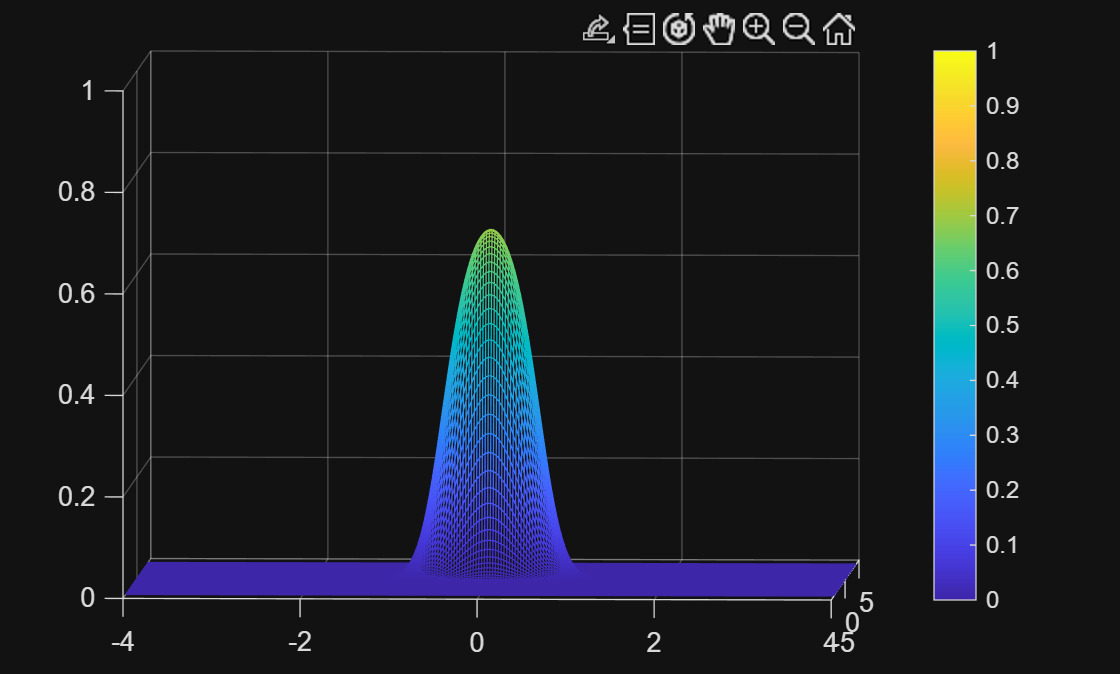

Beta = 0.0001;
VC = 4*pi;
PD = 0.1;

x = linspace(-4,4,256);
y = linspace(-4,4,256);
[X,Y] = meshgrid(x,y);
np = mvnpdf([X(:),Y(:)],[0,0],0.1*eye(2));
np = reshape(np,size(X));

pdetandNotFA = exp(-VC*Beta)*PD;
pFromDist = np.*pdetandNotFA./(np.*pdetandNotFA+(1-pdetandNotFA)./VC);

mesh(x,y,pFromDist)
clim([0,1])
zlim([0,1])
colorbar